# L06_Example

# 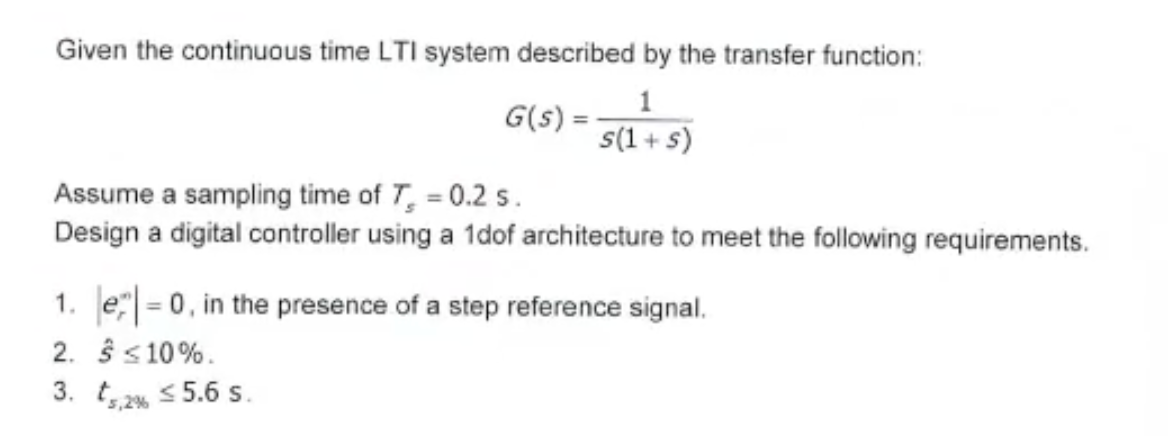

I need to understand how to make the setting of the design.

The plant is described in continuous time, so I need to transform it in discrete time

close all
clear
clc

s = tf('s');
G_ct = 1/(s*(1+s)); % definition of the plant in CT
Ts = 0.2;
G = zpk(c2d(G_ct,Ts,'zoh')); 
%NB I need to epress G in zpk form -> I can immediately recognize what are
%the pole/zero that can be cancelled
[zG, pG, kG] = zpkdata(G,'v')

zG = -0.9355

pG =     1.0000
    0.8187


kG = 0.0187

Now I can split G in A and B

B = kG*[1 -zG]; % I multiply the gain times the vector form of the polinomial
A = conv([1 - pG(1)], [1 - pG(2)]); % multiplication of 2 polynomials in z domain

Q: is it mandatory to write them with vector form and convolution? 

YES because all the polinomials that we need for the computation of the solution to the dioph eq must be represented in vector form

### Steady State requirements

Since e_inf must be 0 in the presence of a step => l=1. I observe that l1 = 1, I have already that pole!!! => No additonal poles are required!!

C(z) will be in the form C(z) = S(z)/R(z) (l2=0)

### Transient requirements

I have to compute the damping coeff according to the relation with the overshoot and wn from the relation with setting time

s_hat = 0.1; % overshoot
t_s = 5.6; % setting time
zeta = abs(log(s_hat))/sqrt(pi^2+log(s_hat)^2); 
wn = 4/(zeta*t_s); 

Now I have to perform the design settings:

I suppose now to perform at first a cancellation of all the stable z-p

Let's take a look at G

G


G =
 
  0.018731 (z+0.9355)
  -------------------
   (z-1) (z-0.8187)
 
Sample time: 0.2 seconds
Discrete-time zero/pole/gain model.


Immediately I can see what are the roots that I can cancel

**I decide to cancel everything that is stable** => I can cancel one zero and one pole

We'll see at the end (after the simulation), that this decision (to cancel everything that is stable) isn't a good decision!

A_plus = [1, -pG(2)];
A_minus = 1; % NB (z-1) does not count!! It's apart
B_plus = [1, -zG];
B_minus = kG;

=> C(z) will have the form (A_plus*S'(z))/(B_plus*R'(z))

Now let's focus on degree condition:

Deg(S') = ... = 0 

Deg(R') = ... = 0

Deg(Am)  = ... = 1 => only one pole to assign!

I have to choose the polynomial according to the roots, that are defined by the second order prototype. But this time this second order prototype degenerates in one order prototype.

How can I choose the roots? I choose them as the real part of the couple of complex conjugate poles if the system was of the second order 

So I choose my pole as -zeta*wn

Once I have chosen the poles, for every pole that I've chosen I compute the sampling transformation to map it into discrete time 

p1c = -zeta*wn; % pole in CT
p1 = exp(p1c*Ts) % sampling transformation -> I get the pole value in DT

p1 = 0.8669


Am = poly(p1);
A_dioph = conv([1 -1], A_minus)

A_dioph =      1    -1


B_dioph = B_minus

B_dioph = 0.0187

At this point, everything is set

M_s = [[A_dioph(:)], [0;B_dioph(:)]];
Gamma = Am';
Theta = M_s\Gamma;
R1 = Theta(1);
S1 = Theta(2);
% [R2,S2] = diop_solver(A_dioph, B_dioph, Am, 0);
% norm(R2-R1, inf)
% norm(S2-S1, inf)
S = conv(A_plus,S1);
R = conv(B_plus,R1);
C = zpk(tf(S,R,Ts))


C =
 
  7.1071 (z-0.8187)
  -----------------
     (z+0.9355)
 
Sample time: 0.2 seconds
Discrete-time zero/pole/gain model.


Everything has been established, but what is missing? I have to check the satisfaction of the requirements -> I have to simulate!!!

(See simulink_basics.mlx)

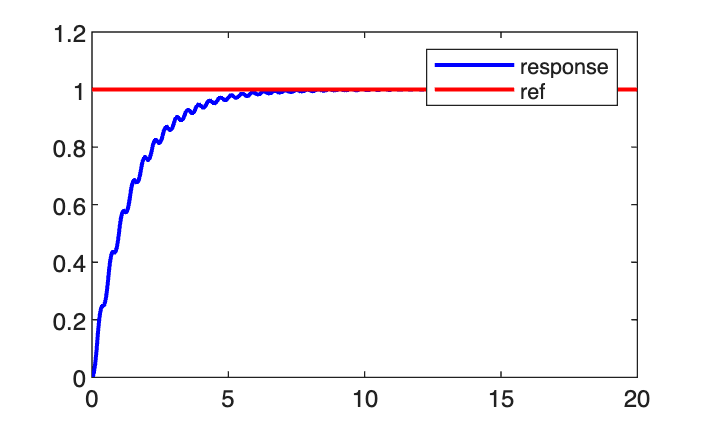

Tend = 100*Ts; % random Tend wrt what I see from plot
sim = sim("sim_unitary_step.slx");

y = sim.y;
r = sim.r;
e = sim.e;
u = sim.u;
u_sampled = sim.u_sampled;

figure(1); title("plot of the response y and the refence r");
plot(y.time, y.data, 'b',"LineWidth",1.5)
hold on
plot(r.time, r.data, 'r', "LineWidth",1.5)
legend("response", "ref")

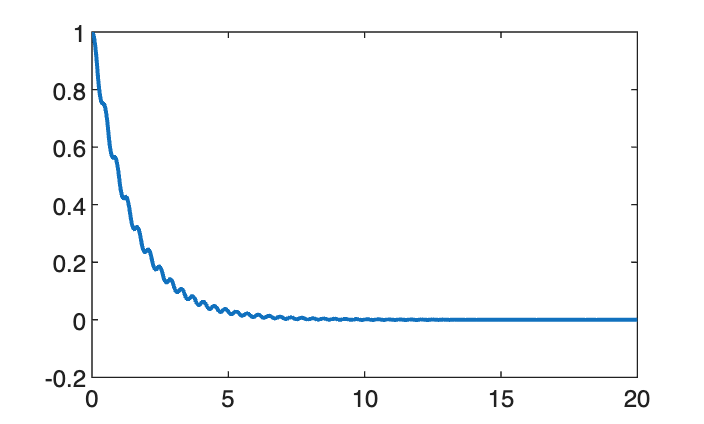


figure(2); title("error")
plot(e.time, e.data, "LineWidth",1.5);

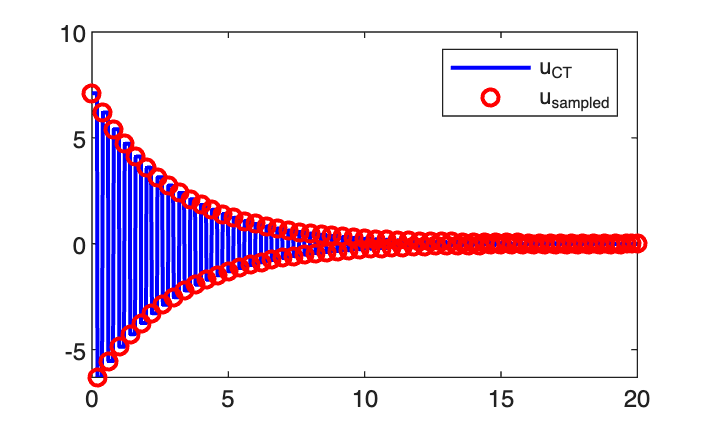


figure(3); title("u vs u_{sampled} (with correct def of u_sampled)")
plot(u.time, u.data, 'b',"LineWidth",1.5);
hold on
plot(u_sampled.time, u_sampled.data, 'ro',"LineWidth",1.5)
legend("u_{CT}", "u_{sampled}")

If I see response plot, I see an oscillatory behaviour!

The control input show an alternate behaviour too (one sample positive, one sample negative,...) => for sure in the response between the ref and the input I have an alternate mode! Moreover, this effect is nothing but the filtering by G_ct of this strange behaviour. So, we explain this strange oscillatory behaviour by the presence of this alternate mode that is present in the tf between the reference and the control input. (Note: this phenomenon is called ringing).

Let's analyse this in DT: I have to compute the tf between r and u. It is what we have define W3. If I compute it, I find that it has a pole at -0.9355 which gives rise to a **natural alternate mode** with this shape (the mode is (-0.9355)^k, that for odd k is negative!). **Why I have this natural mode?** It appears in W3 since I have performed the cancellation of plant zero at -0.9355!!!! (it's the same coeff). In fact, when I do z-p canc, whatever it is (positive or negative), **the cancelled root for sure appears in one of the 4 tf!!! **In this case, we have cancelled a root with negative real part in DT, that is outside the cardioid. So, example shows that it isn't suitable to cancel roots with negative real part in DT, because this cancellation will produce a corresponding pole in one of the 4 tf. (NOTE: it's not a "stability problem", since that cancelled root is stable!). 

Is it a good aspect that response has this behaviour? NO -> this is an unsuitable cancellation => it is not a good idea to cancel z-p that have negative real part in DT -> **this is the physical evident (altough it is allowed (is stable))**

### **Ex 2**

 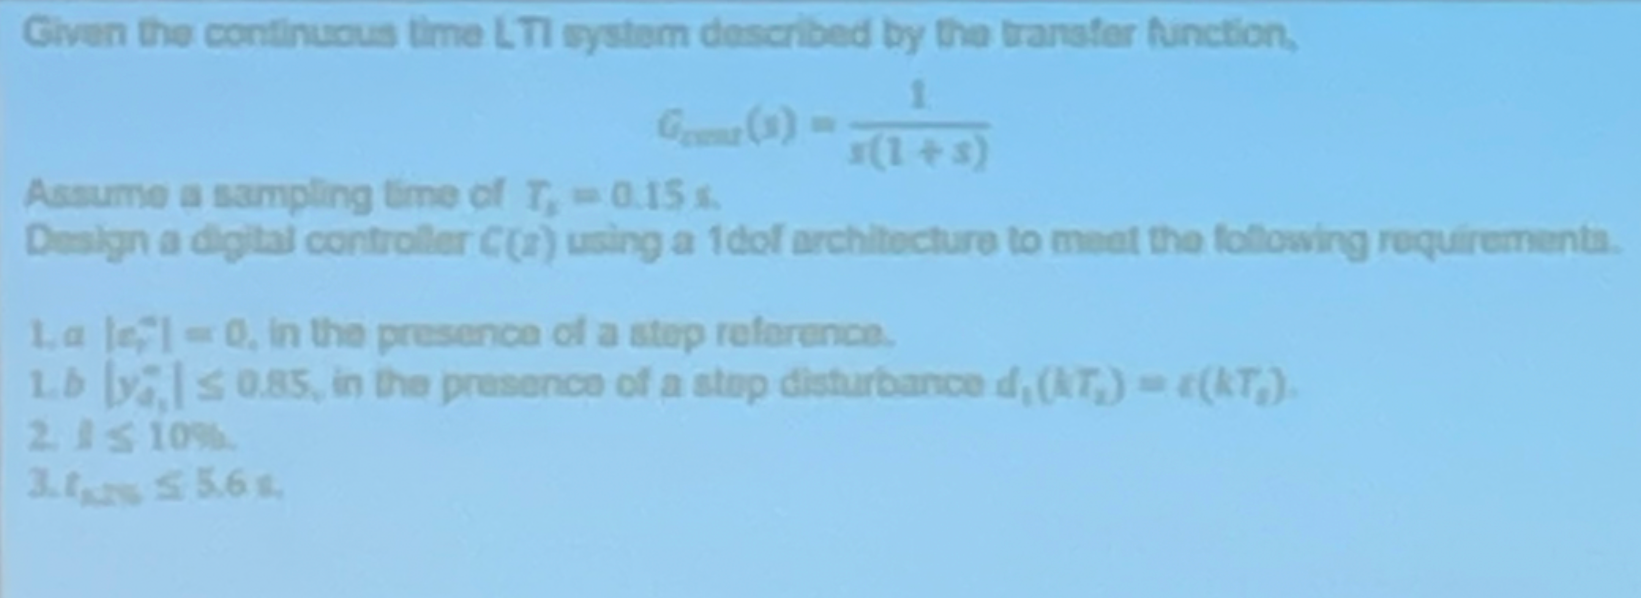

close all
clear
clc

s = tf('s');
G_cont = 1/(s*(1+s));
Ts = 0.15;
z = tf('z', Ts);
G = zpk(c2d(G_cont, Ts, 'zoh'))


G =
 
  0.010708 (z+0.9512)
  -------------------
   (z-1) (z-0.8607)
 
Sample time: 0.15 seconds
Discrete-time zero/pole/gain model.



%NB I need to epress G in zpk form -> I can immediately recognize what are
%the pole/zero that can be cancelled
[zG, pG, kG] = zpkdata(G,'v')

zG = -0.9512

pG =     1.0000
    0.8607


kG = 0.0107

B = kG*[1  -zG];
A = conv([1 -pG(1)], [1 -pG(2)]);

#### SS analysis

e_inf = 0 -> I observe that l1 = 1, I have already that pole!!! => No additonal poles are required!!

y_d1 = 0.85 -> again I don't need extra poles in 0, but I have an extra condition on Kc (see later)

### Transient requirements

I have to compute the damping coeff according to the relation with the overshoot and wn from the relation with setting time

s_hat = 0.1; % overshoot
t_s = 5.6; % setting time
zeta = abs(log(s_hat))/sqrt(pi^2+log(s_hat)^2)*1.2; 
wn = 4/(zeta*t_s); 
% NB if condition are not satisfied I can change a bit the relations!!
% see the 1.2 extra!!!

% G partition -> I CANCEL JUST ONE POLE
A_plus = [1, -pG(2)];
A_minus = 1;
B_plus = kG;
B_minus = [1, -zG];

=> C(z) will have the form (A_plus*S'(z))/(B_plus*R'(z))

Now let's focus on degree condition:

l1 = 1; % power of (z-1) term in G
l2 = 0; % power of (z-1) term in C
l = l1+l2;

Kl = 1/0.85;
n_add = 1; % IMPORTANT!!!! is the extra condition that I have 

deg_A = 2; % G has 2 poles
deg_A1 = 1; % one roots in 1
deg_Aplus = 1;
deg_Aminus = 0;
deg_Bplus = 0;
deg_Bminus = 1;

% by def
deg_S1 = l + deg_Aminus - 1 + n_add

deg_S1 = 1

deg_R2 = deg_A1 - deg_Bplus + l1 - 1 + n_add

deg_R2 = 2

deg_Am = l + deg_Aminus + deg_A1 - deg_Bplus + l1 - 1 + n_add 

deg_Am = 3

For what regard Am, we get:

Since deg(Am) = 3 => we need 3 poles -> we choose 2 complex conjugate poles and one real

p1c = -5*zeta*wn; % pole in CT (NOTE: 5 is a choice)
p1 = exp(p1c*Ts); % sampling transformation -> I get the pole value in DT
p2c = -zeta*wn + 1j*wn*sqrt(1-zeta^2);
p2 = exp(p2c*Ts);
p3c = -zeta*wn - 1j*wn*sqrt(1-zeta^2);
p3 = exp(p3c*Ts);
Am = poly([p1, p2, p3]);
A_dioph = conv([1 -1], A_minus)

A_dioph =      1    -1


B_dioph = B_minus

B_dioph =     1.0000    0.9512


delta_1 = 1; % disturbance
y_delta_1 = 0.85; % limit

extra_eq = [delta_1*ones(1,3), -y_delta_1*polyval(A_plus,1)*ones(1,2)];

Now I can finally solve diophantine equation

[R2, S1] = diop_solver(A_dioph,B_dioph,Am,deg_R2, n_add, extra_eq);
R = conv([1 -1], R2); % I can omit B+ term since B+ = 1
S = conv(A_plus,S1);
C = zpk(tf(S(:)',R(:)', 1))


C =
 
  0.053361 (z-0.9184) (z-0.8607)
  ------------------------------
   (z-1) (z-0.9991) (z-0.4261)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
